# Trefoil path

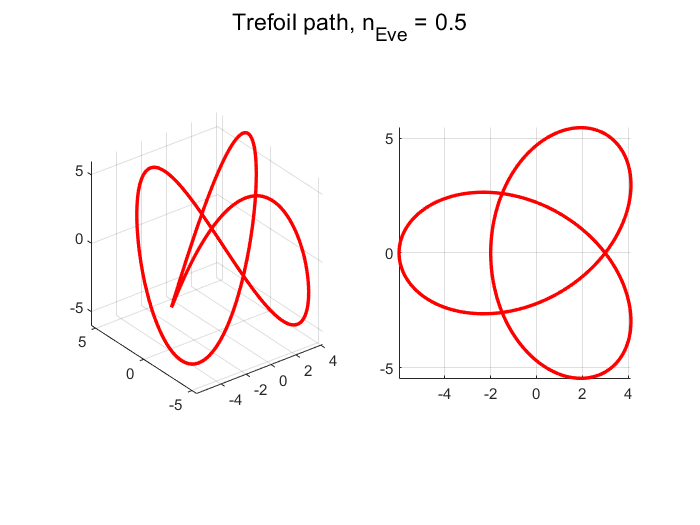

n_eve = 1/2; % 
n_adam = 1/2; % 

nr_eve = 3;
nz_eve = 3;

nr_adam = 2;
nz_adam = 3;

plot_eve = 1;
plot_adam = 0;

eve_loops = 1;
if mod(n_eve, 1) ~= 0
   eve_loops = 2*1/mod(n_eve, 1);
end

adam_loops = 1;
if mod(n_adam, 1) ~= 0
   adam_loops = 2*1/mod(n_adam, 1);
end
c = 1;
v = 0.0*c;

c_alpha = 0.5;

phase0_eve = 0;
phase0_adam = pi;
eve_loops = 4;
rtf = 1.0*r;
eve_path = getTrefoilPaths(v,eve_loops,rtf,nr_eve,nz_eve,phase0_eve);
adam_path = getTrefoilPaths(v,adam_loops,rtf,nr_adam,nz_adam,phase0_adam);

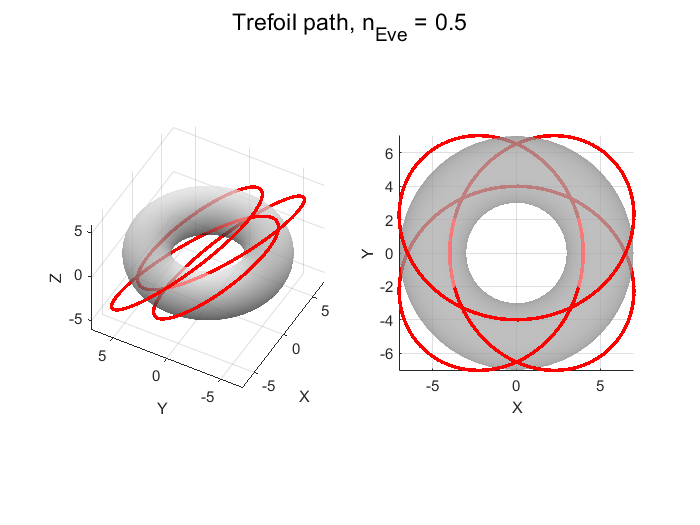


fig2 = figure;
if plot_adam
suptitle(['Trefoil path',...
    ', n_{Eve} = ',num2str(n_eve), ', n_{Adam} = ',num2str(n_adam)])
else
suptitle(['Trefoil path',...
    ', n_{Eve} = ',num2str(n_eve)])
    
end

%% 3D view
subplot(1,2,1)
surf(x,y,z,'FaceAlpha',c_alpha)
shading interp
colormap gray
axis equal
hold on
if plot_eve
    plot3(eve_path(:,1), eve_path(:,2), eve_path(:,3), '-',...
        'Color', eve_color,'LineWidth',2)
end
if plot_adam
    plot3(adam_path(:,1), adam_path(:,2), adam_path(:,3), '-',...
        'Color', adam_color,'LineWidth',2)
end
hold off

xlabel('X')
ylabel('Y')
zlabel('Z')

axis equal
% axis(1.1*[-(R+r) R+r -(R+r) R+r -r r])
grid on
%% Top view
subplot(1,2,2)
surf(x,y,z,'FaceAlpha',0.5)
shading interp
colormap gray
axis equal
hold on
if plot_eve
    plot3(eve_path(:,1), eve_path(:,2), eve_path(:,3), '-',...
        'Color', eve_color,'LineWidth',2)
end
if plot_adam
    plot3(adam_path(:,1), adam_path(:,2), adam_path(:,3), '-',...
        'Color', adam_color,'LineWidth',2)
end
hold off

xlabel('X')
ylabel('Y')
zlabel('Z')

axis equal
% axis(1.1*[-(R+r) R+r -(R+r) R+r -r r])
view(2)


save_image = 0;
if save_image
    saveas(fig2,['quarks_path_n',num2str(n_eve),'.png'])
end


